Setup

nPeriods = 100

nPeriods = 100

nFirms = 1000

nFirms = 1000

tolFixedPoint = 1e-10

tolFixedPoint = 1.0000e-10

nSuppX = 5;
supportX = (1:nSuppX)'

supportX =      1
     2
     3
     4
     5


capPi = 1./(1+abs(ones(nSuppX,1)*(1:nSuppX)-(1:nSuppX)'*ones(1,nSuppX)));
capPi = capPi./(sum(capPi')'*ones(1,nSuppX))

capPi =     0.4380    0.2190    0.1460    0.1095    0.0876
    0.1935    0.3871    0.1935    0.1290    0.0968
    0.1250    0.1875    0.3750    0.1875    0.1250
    0.0968    0.1290    0.1935    0.3871    0.1935
    0.0876    0.1095    0.1460    0.2190    0.4380


beta = [-0.1*nSuppX;0.2]

beta =    -0.5000
    0.2000


delta = [0;1]

delta =      0
     1


rho = 0.95	

rho = 0.9500

Flow payoffs

[u0,u1] = flowpayoffs(supportX,beta,delta); 
[capU0,capU1] = fixedPoint(u0,u1,capPi,rho,tolFixedPoint,@bellman,[],[]);
deltaU = capU1-capU0;

Simulate data

[choices,iX] = simulateData(deltaU,capPi,nPeriods,nFirms);

Nested Fixed Point Maximum Likelihood Estimation

objectiveFunction = @(parameters)negLogLik(choices,iX,supportX,capPi,parameters(1:2),[delta(1);parameters(3)],...
                                           rho,@flowpayoffs,@bellman,@fixedPoint,tolFixedPoint)

objectiveFunction = function_handle with value:
    @(parameters)negLogLik(choices,iX,supportX,capPi,parameters(1:2),[delta(1);parameters(3)],rho,@flowpayoffs,@bellman,@fixedPoint,tolFixedPoint)


startvalues = [-1;-0.1;0.5];
lowerBounds = -Inf*ones(size(startvalues));
lowerBounds(3) = 0;
OptimizerOptions = optimset('Display','iter','Algorithm','interior-point','AlwaysHonorConstraints','bounds',...
                            'GradObj','on','TolFun',1E-6,'TolX',1E-10,'DerivativeCheck','off','TypicalX',[beta;delta(2)]);
[maxLikEstimates,~,exitflag] = fmincon(objectiveFunction,startvalues,[],[],[],[],lowerBounds,[],[],OptimizerOptions)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    9.619559e+04    0.000e+00    1.215e+05


Objective function returned NaN; trying a new point...
    1       7    9.036263e+04    0.000e+00    9.039e+04    8.658e-01
    2      11    9.032890e+04    0.000e+00    8.891e+04    2.165e-01
    3      13    7.667690e+04    0.000e+00    6.573e+04    1.802e+00
    4      14    6.725721e+04    0.000e+00    1.985e+04    1.506e+00
Objective function returned Inf; trying a new point...
    5      19    6.588189e+04    0.000e+00    1.209e+04    1.018e+00
    6      23    6.586153e+04    0.000e+00    2.543e+04    4.719e-01
    7      24    6.526261e+04    0.000e+00    1.006e+04    1.680e-01
    8      25    6.525745e+04    0.000e+00    1.402e+03    5.104e-01
    9      26    6.501895e+04    0.000e+00    8.425e+02    3.000e-01
   10      27    6.501756e+04    0.000e+00    8.060e+01    1.640e-02
   11      28    6.501754e+04    0.000e+00    1.059e+00    2.228e-03
   12      29    6.501754e+04    0.000e+00    1.000e-01    3.208e-05
   13      30    6.501754e+04    0.000e+00    2.000e-02    1.4

maxLikEstimates =    -0.4936
    0.1981
    0.9981


exitflag = 2

[~,~,informationMatrix] = objectiveFunction(maxLikEstimates);
standardErrors = diag(sqrt(inv(informationMatrix)));

%{

The resulting parameter estimates and standard errors are displayed (third and fourth columns), together with the parameters' true (first column) and starting values (second column).

%}

resultsNFXP = table([beta;delta(2)],startvalues,maxLikEstimates,standardErrors,'VariableNames',{'true','start','estim','ste'})

resultsNFXP = 3×4 table
    true    start     estim         ste   
    ____    _____    ________    _________

    -0.5      -1     -0.49364     0.013584
     0.2    -0.1      0.19808    0.0043191
       1     0.5      0.99806     0.013377


%{

\subsection{Extension to an Unknown Markov Transition Matrix for the State}

Finally, consider the more realistic case that $\Pi$ is not known. In this case, \cite{nh94:rust} suggests a two-stage procedure. In the first stage, we estimate $\Pi$ using |estimatePi| and store the results in a $K\times K$ matrix |piHat|.

%}

piHat = estimatePi(iX,nSuppX)

piHat =     0.4394    0.2153    0.1484    0.1074    0.0895
    0.1918    0.3858    0.1973    0.1298    0.0953
    0.1277    0.1847    0.3772    0.1843    0.1262
    0.0956    0.1288    0.1943    0.3857    0.1956
    0.0900    0.1062    0.1449    0.2182    0.4407


%{ 

In the second stage, maximum partial likelihood estimates of $(\beta_0,\beta_1,\delta_1)$ can be computed using the NFXP procedure, with |piHat| replacing |capPi|. This, with the question how the first-stage sampling error affects the precision of the second-stage estimator of $(\beta_0,\beta_1,\delta_1)$, is left for the exercises.

\section{Student Exercises\label{exercises}}

\subsection{Theoretical Exercises}

    \paragraph{Theoretical Exercise 1} Prove that $\Psi$ is a contraction.

    \paragraph{Theoretical Exercise 2} Is $\rho$ identified in the example model? What about $\delta_0$? (To the extent that these are identified, you may want to extend your numerical experiments below to include their estimation.) See \cite{are10:abbring} for results and references.

    \paragraph{Theoretical Exercise 3} Show the equivalence of policy iteration

    and the Newton-Kantorovich method for solving $U-\Psi(U)=0$ for $U$ (see

    Appendices \ref{contractions.computation} and \ref{contractions.DP}). Read about the 

    properties of policy iteration and discuss what these imply about the

    convergence properties of the Newton-Kantorovich method. Does

    policy iteration converge in a finite number of steps? Why (not)?

\subsection{Computational Exercises}

The computational exercises typically ask you to modify the code so that it can handle alternative econometric procedures and models. This often requires that you adapt the analytic computation of the derivatives of the log likelihood. It may be convenient to first (or only) work with numerical derivatives by setting the option "GradObj" in |fmincon| or its alternative to "off"; this allows you to find the estimates without using the analytical gradient in the optimization step.

Once you have coded up the analytical derivatives (in order to use them in the optimization step and to obtain an estimate of the standard errors), you are advised to verify them against numerical derivatives, for example by setting the option "DerivativeCheck" in |fmincon| to "on" (however, make sure to set this option to "off" once you have verified the derivatives and start using the code for repeated, e.g. Monte Carlo, calculations).

    \paragraph{Computational Exercise 1} Extend the script in |dynamicDiscreteChoice.m| with a single simulation to a Monte Carlo experiment in which estimates are computed for a sequence of simulated data sets (for now, as in |dynamicDiscreteChoice.m|, take $\Pi$ to be known). Keep track of the estimates and report statistics such as their means and standard deviations. Compare the latter to asymptotic standard errors. Make sure to set the seed of the random number generator so that your numerical results can be replicated. Note that you can also use this Monte Carlo setup in later questions to study the finite-sample performance of the various procedures studied.

    \paragraph{Computational Exercise 2} For the case of estimating the demand for differentiated products using NFXP maximum likelihood, as in \cite{ecta95:berryetal}, \cite{ecta12:dubeetal} claim that it is important to carefully balance the convergence tolerances used in the inner (contraction) loop and the outer (likelihood maximization) loop. In particular, they argue that the inner loop needs to be computed at a much higher precision than the tolerance used in the outer loop. Experiment with the values of |tolFixedPoint| on the one hand and the tolerances in the |tolX| and |tolFun| fields of |OptimizerOptions| on the other hand to investigate this issue in the context of this package's firm entry and exit problem.

    \paragraph{Computational Exercise 3} Implement the MPEC approach to maximum likelihood estimation of our structural model, as advocated by \cite{ecta12:juddsu}.

		\begin{itemize} 

		\item First, modify |negLogLik| so that it it takes $(U_0,U_1)$ or $\Delta U$ as an input argument (instead of solving the model for them) and computes the log (partial) likelihood directly from the choice probabilities implied by $\Delta U$.

        \item Then, extend the script in |dynamicDiscreteChoice.m| so that it alternatively maximizes the log likelihood with respect to both the parameters of interest and the values of $\Delta U$, subject to the constraint on $\Delta U$ implied by $U=\Psi(U)$ (which can be specified using the function |bellman|).

		\end{itemize}

		Would you expect the NFXP and MPEC approaches to give the same estimates

		of the parameters of interest (up to numerical precision)? How is the

		relative numerical performance of both procedures? Which one is faster?

		Compare your results to those in \cite{ecta16:iskhakovetal} and explain.

    \paragraph{Computational Exercise 4} Compute the two-stage maximum partial likelihood estimates of $(\beta_0,\beta_1,\delta_1)$ for the case that $\Pi$ is not known. Are the estimators of the standard errors that assume $\Pi$ known consistent if $\Pi$ is estimated instead? Read \cite{nh94:rust} and explain why the two-stage estimator of $(\beta_0,\beta_1,\delta_1)$ is not efficient. The full information maximum likelihood (FIML) estimator estimates all parameters, including the ones in $\Pi$, simultaneously by maximizing the full likelihood for the observed state transitions and choices. Write an alternative for |negLogLik| that codes up this likelihood function and adapt the estimation script so that it obtains the FIML estimates and their estimated standard errors. Do not code up the gradient and do not use it in the likelihood maximization. Perform a Monte Carlo study of the two-stage and FIML estimators of $(\beta_0,\beta_1,\delta_1)$. For both estimators, report the means and standard deviations of the estimates of $(\beta_0,\beta_1,\delta_1)$ and the average estimates of the standard errors across Monte Carlo simulations. Compare and discuss. Finally, discuss the three-stage approach suggested by \cite{nh94:rust}.

    \paragraph{Computational Exercise 5} Implement a simulation-based two-step estimator along the lines of \cite{res94:hotzetal}, \cite{nh94:rust}, and \cite{ecta07:bajarietal}.

		\begin{itemize} 

		\item Add a new function for nonparametrically estimating the choice probabilities $p(a|X_t,A_{t-1})\equiv\Pr(A_t=a|X_t,A_{t-1})$ over the support of $(X_t,A_{t-1})$. With enough data and a finite state space, you can simply use the conditional sample frequency. 

		\item Add (to this same function or in a new function) a procedure for estimating $\Delta U$ by inverting the estimated choice probabilities (as proposed by \cite{res93:hotzmiller} and \cite{res94:hotzetal}). 

		\item Add a new function for simulating a given number of state (including $\varepsilon_t$) and choice paths of some given length from each state observed in the data and for each first choice that can be made at the beginning of the path. Make use of the linearity of the flow utility in the parameters to reduce the dimensionality of the objects returned by this function and needed for constructing the objective in the next step.

		\item Adapt |negLogLik| into an objective function that takes nonparametric estimates of $p$ or $\Delta U$ and (a relevant summary of) simulated states and choices as inputs. As possible objectives to be minimized, implement both a weighted distance between the nonparametric estimates of $\Delta U$ and simulated values of $\Delta U$, and minus a log pseudo-likelihood based on the choice probabilities implied by the simulated values of $\Delta U$. When doing so exploit linearity of the flow utilities in the parameters.

		\item Finally, extend the script in |dynamicDiscreteChoice.m| so that it successively calls these functions to implement a two step procedure for estimating the model, as in \cite{res93:hotzmiller} and \cite{res94:hotzetal}. Analyze the numerical and statistical performance of this procedure with both of the possible objective functions implemented and compare. Discuss the theoretical relation between both approaches; see \cite{res08:pesendorferschmidtdengler}.

		\end{itemize}

	See the course slides for a brief and general description of this procedure and \cite{nh94:rust} for a detailed algorithm, with discussion. Note that the algorithm described in \cite{nh94:rust} is similar to that of \cite{ecta07:bajarietal} for games that we will discuss later in the course. Both build on the ideas of \cite{res94:hotzetal}, who use the special logit structure to simplify the simulation (see the discussion in \cite{ecta07:bajarietal}). 

    \paragraph{Computational Exercise 6} Extend the code for simulation and NFXP estimation so that it can handle a finite number of unobserved types, as in the work of \cite{Eckstein_Wolpin_1990_Econometrica}, \cite{Keane_Wolpin_1997_JPE}, and \cite{Eckstein_Wolpin_1999_Econometrica}. Specifically, suppose that there are two types in the population, one with entry cost $\delta_1^1$ and the other with entry cost $\delta_1^2$. The firms are distributed across both unobserved entry cost types independently from all other variables in the model. We would like to estimate $\beta_0,\beta_1,\delta_1^1,\delta_1^2$, and the share of agents with entry cost $\delta_1^1$. To this end:

		\begin{itemize} 

		\item Extend |simulateData| so that it randomly draws an entry cost from a distribution with two points of support, $\delta_1^1$ and $\delta_1^2$, and simulates choice data corresponding to the entry cost drawn, for each firm, independently across firms. 

		\item Extend |negLogLik| so that it computes each firm's likelihood contribution as the mixture (expectation) of the likelihood contributions for each entry cost type (which are given by the current specification of the likelihood for homogeneous firms) over the distribution of these two types in the population of firms.

		\item Finally, extend the script in |dynamicDiscreteChoice.m| so that it successively calls these functions. Check whether you can recover the entry cost distribution, and the other parameters, well.  

		\end{itemize}

    \paragraph{Computational Exercise 7} Implement a version of the two-step estimator of \cite{res94:hotzetal} that similarly allows for a finite number of unobserved types. To this end, combine this estimator with the EM algorithm as in \cite{ecta11:arcidiaconomiller} (see also \cite{are11:arcidiaconoellickson}).

    \paragraph{Computational Exercise 8} Perform a Monte Carlo study of all the estimators that you have implemented. Evaluate and compare their numerical performance as measured in terms of convergence success and computation time; and their finite sample statistical performance in terms of, among other things, mean squared errors. Experiment with different choices of the numerical design parameters, such as the inner and outer loop tolerances used in the NFXP procedure.

    \paragraph{Computational Exercise 9} Extend |fixedPoint| so that it has the option to compute $U$ using the Newton-Kantorovich method instead of successive approximations, or a hybrid method that combines both (as in \cite{ecta87:rust}). Note that, with a finite state space as in our example, the Newton-Kantovorich method reduces to the Newton-Raphson method and requires the Jacobian $\partial\tilde\Psi_\theta(\bar U)/\partial\bar U'$ computed in an intermediate step of |negLogLik|. Explore the numerical performance of the various methods. What is your preferred method?

\begin{bibliography}

    \bibitem[Abbring (2010)]{are10:abbring} Abbring, Jaap H. (2010). Identification of dynamic discrete choice models. \textit{Annual Review of Economics} 2, 367-394.

    \bibitem[Aguirregabiria and Mira (2002)]{ecta02:aguirregabiriamira} Aguirregabiria, Victor and Pedro Mira (2002). Swapping the nested fixed point algorithm: A class of estimators for discrete Markov decision models. \textit{Econometrica} 70(4), 1519-1543.  

    \bibitem[Arcidiacono and Ellickson (2011)]{are11:arcidiaconoellickson} Arcidiacono, Peter and Paul B. Ellickson (2011).  Practical methods for estimation of dynamic discrete choice models. \textit{Annual Review of Economics} 3, 363-394.

    \bibitem[Arcidiacono and Miller (2011)]{ecta11:arcidiaconomiller} Arcidiacono, Peter and Robert A. Miller (2011).  Conditional choice probability estimation of dynamic discrete choice models with unobserved heterogeneity. \textit{Econometrica} 79, 1823-1867.

    \bibitem[Bajari, Benkard, and Levin (2007)]{ecta07:bajarietal}Bajari, Patrick, Lanier Benkard, and Jonathan Levin (2007). Estimating dynamic models of imperfect competition. \textit{Econometrica} 75(5), 1331-1370.

    \bibitem[Berry, Levinsohn, and Pakes (1995)]{ecta95:berryetal} Berry, Steven, James Levinsohn, and Ariel Pakes (1995). Automobile prices in market equilibrium. \textit{Econometrica} 63, 841-890.

    \bibitem[Dixit (1989)]{jpe89:dixit}Dixit, Avinash K. (1989). Entry and exit decisions under uncertainty. \textit{Journal of Political Economy} 97(3), 620-638.

    \bibitem[Eckstein and Wolpin (1990)]{Eckstein_Wolpin_1990_Econometrica} Eckstein, Zvi and Kenneth I. Wolpin (1990). Estimating a market equilibrium search model from panel data on individuals. \textit{Econometrica} 58(4), 783-808.

    \bibitem[Eckstein and Wolpin (1999)]{Eckstein_Wolpin_1999_Econometrica} Eckstein, Zvi and Kenneth I. Wolpin (1999). Why youths drop out of high school: The impact of preferences, opportunities, and abilities. \textit{Econometrica} 67(6), 1295-1339.

    \bibitem[Hotz and Miller (1993)]{res93:hotzmiller}Hotz, V. Joseph and Robert A. Miller (1993). Conditional choice probabilities and the estimation of dynamic models. \textit{Review of Economic Studies} 60, 497-529.

    \bibitem[Hotz et al. (1994)]{res94:hotzetal}Hotz, V. Joseph, Robert A. Miller, Seth Sanders and Jeffrey Smith (1994). A simulation estimator for dynamic models of discrete choice. \textit{Review of Economic Studies} 61(2), 265-289.

    \bibitem[Iskhakov et al. (2016)]{ecta16:iskhakovetal} Iskhakov, Fedor, Jinhyuk Lee, John Rust, Bertel Schjerning and Kyoungwon Seo (2016). Comment on "Constrained optimization approaches to estimation of structural models". \textit{Econometrica} 84(1), 365-370.

    \bibitem[Judd (1998)]{mit98:judd}Judd, Kenneth L. 1998. \textit{Numerical Methods in Economics}.  MIT Press. Cambridge, MA.

    \bibitem[Judd and Su (2012)]{ecta12:juddsu} Judd, Kenneth L. and Che-Lin Su (2012). Constrained optimization approaches to estimation of structural models. \textit{Econometrica} 80(5), 2213-2230.

    \bibitem[Keane and Wolpin (1997)]{Keane_Wolpin_1997_JPE} Keane, Michael P. and Kenneth I. Wolpin (1997). The career decisions of young men. \textit{Journal of Political Economy} 105(3), 473-522.

    \bibitem[Ljungqvist and Sargent (2000)]{mit00:ljungqvistsargent} Ljungqvist, Lars and Thomas J. Sargent (2000). \textit{Recursive Macroeconomic Theory}, \url{http://www.econ.yale.edu/smith/econ510a/sargent3.pdf}{Second edition}. MIT Press. Cambridge, MA.

    \bibitem[McFadden (1981)]{McFadden_1981_probabilistic} McFadden, Daniel (1981). Econometric models of probabilistic choice. In C. Manski and D. McFadden (Eds.). \textit{Discrete Data with Econometric Applications}. MIT Press. Cambridge, MA.

    \bibitem[Pesendorfer and Schmidt-Dengler (2008)]{res08:pesendorferschmidtdengler} Pesendorfer, Martin and Philipp Schmidt-Dengler (2008). Asymptotic least squares estimators for dynamic games. \textit{Review of Economic Studies} 75(3), 901-928.

    \bibitem[Puterman and Brumelle (1979)]{mor79:putermanbrumelle} Puterman, Martin L. and Shelby L. Brumelle (1979). On the convergence of policy iteration in stationary dynamic programming. \textit{Mathematics of Operations Research} 4.1, 60-69.

    \bibitem[Rust (1987)]{ecta87:rust} Rust, John (1987). Optimal replacement of GMC bus engines: An empirical model of Harold Zurcher. \textit{Econometrica} 55, 999-1033.

    \bibitem[Rust (1994)]{nh94:rust} Rust, John (1994). Structural estimation of Markov decision processes. In R. Engle and D. McFadden (Eds.). \textit{Handbook of Econometrics} 4, 3081-3143. North-Holland. Amsterdam.

    \bibitem[Stokey, Lucas, and Prescott (1989)]{harvard1989StokeyLucasPrescott} Stokey, Nancy L. and Robert E. Lucas (with Edward C. Prescott) (1989). \textit{Recursive Methods in Economic Dynamics}. Harvard University Press. Cambridge, MA.

\end{bibliography}

\appendix

\section{Contractions and Dynamic Programming\label{contractions}}

See e.g. \cite{harvard1989StokeyLucasPrescott} and \cite{mit98:judd} for a rigorous and comprehensive treatment of the topics in this appendix and their economic applications.

\subsection{Definitions\label{contractions.definitions}}

A \emph{metric space} is a set $\cal{U}$ with a metric $m:\cal{U}\times\cal{U}\rightarrow\mathbb{R}$ such that, for any $U,U',U''\in\cal{U}$,

\begin{enumerate}

	\item $m(U,U')=0$ if and only if $U=U'$,

	\item $m(U,U')=m(U',U)$, and 

	\item $m(U,U'')\leq m(U,U')+m(U',U'')$ (triangle inequality).

\end{enumerate}

A \emph{Cauchy sequence} in $({\cal U},m)$ is a sequence $\{U_n\}$ in ${\cal U}$ such that, for each $\epsilon>0$, there exists some $n(\epsilon)\in\mathbb{N}$ such that $m(U_n,U_{n'})<\epsilon$ for all $n,n'\geq n(\epsilon)$. 

A metric space $({\cal U},m)$ is \emph{complete} if every Cauchy sequence in $({\cal U},m)$  converges to a point in ${\cal U}$.

A map $\Psi:{\cal U}\rightarrow{\cal U}$ is a \emph{contraction with modulus $\rho\in(0,1)$} if $m\left[\Psi(U),\Psi(U')\right]\leq \rho m(U,U')$ for all $U,U'\in{\cal U}$.

\subsection{Contraction Mapping (Banach Fixed Point) Theorem\label{contractions.Banach}}

If $({\cal U},m)$ is a complete metric space and $\Psi:{\cal U}\rightarrow{\cal U}$ is a contraction, then there exists a unique $U\in{\cal U}$ such that $U=\Psi(U)$. Furthermore, for any $U_0\in{\cal U}$, the sequence $\{U_n\}$ with $U_{n+1}=\Psi(U_{n})$, $n\in\mathbb{N}$, converges to $U$.

\paragraph{Sketch of Proof}

Suppose $U,U'\in{\cal U}$ are such that $U=\Psi(U)$ and $U'=\Psi(U')$. Then, $0\leq m(U,U')=m\left[\Psi(U),\Psi(U')\right]\leq\rho m(U,U')$ for some $\rho\in(0,1)$. Consequently, $m(U,U')=0$ and $U=U'$.

Because $\Psi$ is a contraction, any  $\{U_n\}$ it generates is a Cauchy sequence. Because $({\cal U},m)$ is complete, it converges to some $U\in{\cal U}$. Because contractions are continuous, $U=\Psi(U)$.

\subsection{Computing the Fixed Point of a Contraction\label{contractions.computation}}

The method of \emph{successive approximations} directly applies the Contraction Mapping Theorem and approximates the fixed point $U$ of a contraction $\Psi$ with the sequence $\{U_n\}$  generated from $U_{n+1}=\Psi(U_n)$ on a finitely discretized state space. This method has global but linear convergence.

    linear map defined by the appropriate finite dimensional Jacobian, as in |negLogLik|).

\subsection{Blackwell's Sufficient Conditions for a Contraction\label{contractions.Blackwell}}

Let ${\cal U}$ be the space of functions $U:{\cal X}\rightarrow\mathbb{R}$ such that $\sup|U|<\infty$ ($U$ bounded), with metric $m(U,U')=\sup|U-U'|$. Suppose that, for some $\rho\in(0,1)$, $\Psi:{\cal U}\rightarrow{\cal U}$ satisfies

\begin{enumerate}

\item (monotonicity) $\Psi(U)\leq \Psi(U')$ and

\item (discounting) $\Psi(U+\gamma)\leq \Psi(U)+\rho\gamma$

\end{enumerate}

for all $U,U'\in{\cal U}$ such that $U\leq U'$ and all $\gamma\in(0,\infty)$. Then, $\Psi$ is a contraction with modulus $\rho$.

\paragraph{Sketch of Proof}

Let $U,U'\in{\cal U}$ be such that  $U\leq U'$. Note that $U\leq U'+m(U,U')$, so that $\Psi(U)\leq \Psi(U')+\rho m(U,U')$ by monotonicity and discounting. Similarly,   $\Psi(U')\leq \Psi(U)+\rho m(U,U')$. Thus, $m\left[\Psi(U),\Psi(U')\right]\leq\rho m(U,U')$.

 \subsection{Application to Dynamic Programming\label{contractions.DP}} 

The choice-specific value function $U$ is a fixed point of $\Psi$, which satisfies Blackwell's sufficient conditions with $\rho$ equal to the discount factor. 

\begin{itemize}

\item Under regularity conditions such that $U$ is bounded,  this ensures that it is the unique fixed point of a contraction on the complete (Banach) space $({\cal U},m)$ of bounded functions. 

\item If ${\cal U}'\subset{\cal U}$ is closed and  $\Psi(U')\in{\cal U}'$ for all $U'\in{\cal U}'$, then $\Psi$ is a contraction on the complete subspace $({\cal U}',m)$, so that $U\in{\cal U}'$ (examples: monotonicity, continuity, etcetera).

\item $U$ can be computed by successive approximations, the Newton-Kantorovich method, or a hybrid algorithm as in \cite{ecta87:rust}.

\end{itemize}

In this context, the method of successive approximations is alternatively

referred to as \emph{value iteration}. Moreover, the Newton-Kantorovich method

is closely related to an alternative method called \emph{policy iteration}. Each of this method's iterations takes a value function as input, determines the corresponding

optimal policy, and then gives the values of applying that policy forever as

output (see e.g. \cite{mit00:ljungqvistsargent}, Section 3.1.1, which refers to

this method as \emph{Howard's policy improvement algorithm}, or \cite{nh94:rust}, Section 2.5). 

\cite{mor79:putermanbrumelle} show that policy iteration is generally

equivalent to applying the Newton-Kantorovich method to finding the fixed point

of the Bellman equation (in the sense that both produce the same sequence of value functions when starting from the same value). \cite{mit00:ljungqvistsargent}, Section 4.4, present and develop this result for the special case of a finite state space. 

Finally, for our example's special case of a finite ${\cal X}$,

\cite{ecta02:aguirregabiriamira}'s Proposition 1 establishes that policy

iteration is equivalent to applying the Newton-Kantorovich method to finding a

fixed point of the Bellman-like operator $\Psi$ (which \cite{ecta02:aguirregabiriamira} refer to as a \emph{smoothed} Bellman operator).

\section{Miscellaneous Utilities\label{misc}}

This section documents some miscellaneous utilities that are called by the main functions. At this point, it only includes |randomDiscrete|.

\input[4..end]{randomDiscrete.m}

%}

## CCP: calculating value function without iteration

Recall that $X_t$ can take on $K$ values. Let the $K$-vector $\mathbf{p}_d$ be the probability that a firm is in the market given that the choice in the previous period was $d$.

We can also calculate the two vectors of probabilities that are generated by the model:

prob0 = 1./(1+exp(capU0(:,1)-capU1(:,1))); % not in market in previous period
prob1 = 1./(1+exp(capU0(:,2)-capU1(:,2))); % in market in previous period

From this we can calculate vectors of correction terms $\mathbf{c}_d = -\log(\mathbf{p}_d)$:

correctionTerm0 = [-log(1-prob0) -log(prob0)];
correctionTerm1 = [-log(1-prob1) -log(prob1)];

Denote the $K$-vectors containing the flow utilities as a function of the current state and past choice $d$ by $\mathbf{u}_d$.

An important implication of Hotz and Miller (1993) is that the value function is given by

 $U = \left( I - \rho\pmatrix{[(1-\mathbf{p}_0)_{\times K}] \circ \Pi & [(\mathbf{p}_0)_{\times K}] \circ \Pi \cr [(1-\mathbf{p}_1)_{\times K}] \circ \Pi & [(\mathbf{p}_1)_{\times K}] \circ \Pi}
\right)^{-1} \left( \sum_d \mathbf{p}_d*[\mathbf{u}_d + \mathbf{c}_d] \right)$.

See Aguirregabiria and Mira (2002) and Arcidiacono and Ellickson (2011) for additional discussion.

We can code this up and obtain

bigPi = [repmat(1-prob0,1,size(capPi,2)).*capPi repmat(prob0,1,size(capPi,2)).*capPi;
    repmat(1-prob1,1,size(capPi,2)).*capPi repmat(prob1,1,size(capPi,2)).*capPi];
capUCcpLong = (eye(size(bigPi,1))-rho*bigPi) ...
    \ sum([(1-prob0) prob0;(1-prob1) prob1] .* ...
    ([u0(:,1) u1(:,1);u0(:,2) u1(:,2)] + [correctionTerm0;correctionTerm1]),2)

capUCcpLong =    10.1837
   10.2971
   10.4427
   10.6048
   10.7633
   10.6002
   10.7663
   10.9665
   11.1826
   11.3921


We can also compare this to the value function that is implied by we have obtained using value function iteration:

capU = log(exp(capU0)+exp(capU1));
table(capUCcpLong,capU(:),'VariableNames',{'CCP','value function iteration'})

ans = 10×2 table
     CCP      value function iteration
    ______    ________________________

    10.184             10.184         
    10.297             10.297         
    10.443             10.443         
    10.605             10.605         
    10.763             10.763         
      10.6               10.6         
    10.766             10.766         
    10.967             10.967         
    11.183             11.183         
    11.392             11.392         


## Understanding the correction terms

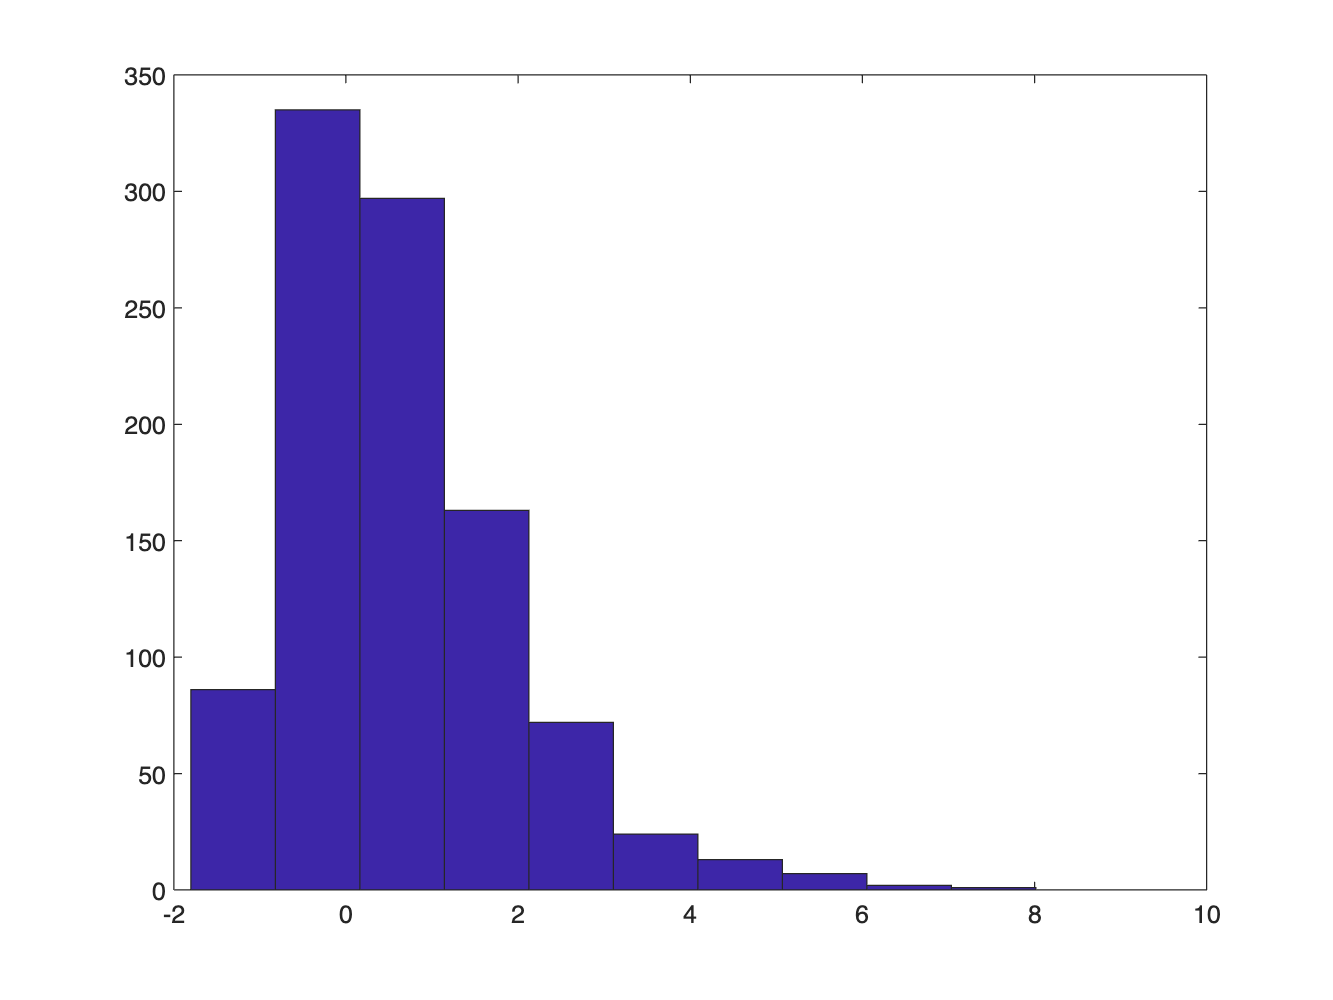

epsilon1 = -random('ev',zeros(1000000,1),ones(1000000,1));
epsilon2 = -random('ev',zeros(1000000,1),ones(1000000,1));
epsilon3 = -random('ev',zeros(1000000,1),ones(1000000,1));


hist(epsilon0)
mean(epsilon0)

u1 = 0.9 * ones(1000000,1) + epsilon1;
u2 = 2.1 * ones(1000000,1) + epsilon2;
u3 = 3.5 * ones(1000000,1) + epsilon3;

choose2 = u2>u1 & u2>u3;
mean(epsilon2(choose2==1))
probChoose2 = exp(2.1)/(exp(0.9)+exp(3.5))
-log(probChoose2)


## Using CCP for maximum likelihood estimation

We first estimate the choice probabilities:

startvalues = [-1;-0.1;0.5];
lowerBounds = -Inf*ones(size(startvalues));
lowerBounds(3) = 0;
OptimizerOptions = optimset('Display','iter','Algorithm','interior-point','AlwaysHonorConstraints','bounds',...
                            'GradObj','off','TolFun',1E-6,'TolX',1E-10,'DerivativeCheck','off','TypicalX',[beta;delta(2)]);

objectiveFunctionCcpO = @(parameters)negLogLikCcp(choices,prob0,prob1,iX,supportX,capPi,...
    parameters(1:2),[delta(1);parameters(3)],rho,@flowpayoffs)

objectiveFunctionCcpO = function_handle with value:
    @(parameters)negLogLikCcp(choices,prob0,prob1,iX,supportX,capPi,parameters(1:2),[delta(1);parameters(3)],rho,@flowpayoffs)



[maxLikEstimatesCcpO,~,exitflag,~,~,~,informationMatrixCcpO] = fmincon(objectiveFunctionCcpO,startvalues,...
    [],[],[],[],lowerBounds,[],[],OptimizerOptions)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.052503e+05    0.000e+00    1.581e+05
Objective function returned Inf; trying a new point...
    1      13    9.800139e+04    0.000e+00    1.202e+05    8.659e-01
Objective function returned Inf; trying a new point...
    2      18    9.655570e+04    0.000e+00    1.180e+05    3.922e-01
Objective function returned Inf; trying a new point...
    3      26    6.664703e+04    0.000e+00    2.964e+04    3.576e-01
Objective function returned Inf; trying a new point...
    4      33    6.585604e+04    0.000e+00    2.405e+04    6.031e-01
    5      37    6.541984e+04    0.000e+00    1.573e+04    2.951e-01
    6      41    6.503376e+04    0.000e+00    4.043e+02    2.588e-01
    7      45    6.501910e+04    0.000e+00    7.442e+02    9.239e-02
    8      49    6.501754e+04    0.000e+00    4.362e+01    1.724e-02
    9      53    6.501754e+04    0

maxLikEstimatesCcpO =    -0.4936
    0.1981
    0.9981


exitflag = 2

informationMatrixCcpO = 1.0e+05 *

    3.8651    2.5767   -5.6055
    2.5767    1.7456   -3.5634
   -5.6055   -3.5634    9.6531


standardErrorsCcpO = diag(sqrt(inv(informationMatrixCcpO)));

laggedChoices = [zeros(1,size(choices,2));choices(1:end-1,:)];
prob0Hat = zeros(nSuppX,1);
prob1Hat = zeros(nSuppX,1);
for k=1:nSuppX
    prob0Hat(k) = sum(choices(iX==k & laggedChoices==0))/length(choices(iX==k & laggedChoices==0));
    prob1Hat(k) = sum(choices(iX==k & laggedChoices==1))/length(choices(iX==k & laggedChoices==1));    
end

objectiveFunctionCcpE = @(parameters)negLogLikCcp(choices,prob0Hat,prob1Hat,iX,supportX,capPi,...
    parameters(1:2),[delta(1);parameters(3)],rho,@flowpayoffs)

objectiveFunctionCcpE = function_handle with value:
    @(parameters)negLogLikCcp(choices,prob0Hat,prob1Hat,iX,supportX,capPi,parameters(1:2),[delta(1);parameters(3)],rho,@flowpayoffs)



[maxLikEstimatesCcpE,~,exitflag,~,~,~,informationMatrixCcpE] = fmincon(objectiveFunctionCcpE,startvalues,...
    [],[],[],[],lowerBounds,[],[],OptimizerOptions)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4    1.051930e+05    0.000e+00    1.578e+05
Objective function returned Inf; trying a new point...
    1      13    9.794250e+04    0.000e+00    1.200e+05    8.659e-01
Objective function returned Inf; trying a new point...
    2      18    9.649729e+04    0.000e+00    1.178e+05    3.922e-01
Objective function returned Inf; trying a new point...
    3      26    6.663971e+04    0.000e+00    2.953e+04    3.576e-01
Objective function returned Inf; trying a new point...
    4      33    6.585081e+04    0.000e+00    2.394e+04    6.035e-01
    5      37    6.541321e+04    0.000e+00    1.559e+04    2.936e-01
    6      41    6.503368e+04    0.000e+00    4.034e+02    2.568e-01
    7      45    6.501910e+04    0.000e+00    7.421e+02    9.224e-02
    8      49    6.501754e+04    0.000e+00    4.353e+01    1.725e-02
    9      53    6.501754e+04    0

maxLikEstimatesCcpE =    -0.4936
    0.1981
    0.9981


exitflag = 2

informationMatrixCcpE = 1.0e+06 *

    0.4526   -1.8499    1.0807
   -1.8499    7.7598   -4.2353
    1.0807   -4.2353    2.7468


standardErrorsCcpE = diag(sqrt(inv(informationMatrixCcpE)));


resultsAll = table([beta;delta(2)],maxLikEstimates,standardErrors,...
    maxLikEstimatesCcpO,standardErrorsCcpO,maxLikEstimatesCcpE,standardErrorsCcpE,...
    'VariableNames',{'true','NFXPestim','NFXPste','CCPOestim','CCPOste','CCPEestim','CCPEste'})

resultsAll = 3×7 table
    true    NFXPestim     NFXPste     CCPOestim     CCPOste     CCPEestim    CCPEste
    ____    _________    _________    _________    _________    _________    _______

    -0.5    -0.49364      0.013584    -0.49364      0.029638    -0.49362      1.5803
     0.2     0.19808     0.0043191     0.19808      0.035295     0.19807     0.23599
       1     0.99806      0.013377     0.99806     0.0047671     0.99808     0.25788


function nll = ...
         negLogLikCcp(choices,prob0,prob1,iX,supportX,capPi,beta,delta,rho,flowpayoffs)

    nSuppX = size(supportX,1);
    [u0,u1] = flowpayoffs(supportX,beta,delta);
    
    correctionTerm0 = [-log(1-prob0) -log(prob0)];
    correctionTerm1 = [-log(1-prob1) -log(prob1)];
    
    bigPi = [repmat(1-prob0,1,size(capPi,2)).*capPi repmat(prob0,1,size(capPi,2)).*capPi;
        repmat(1-prob1,1,size(capPi,2)).*capPi repmat(prob1,1,size(capPi,2)).*capPi];

    capUCcpLong = (eye(size(bigPi,1))-rho*bigPi) ...
        \ sum([(1-prob0) prob0;(1-prob1) prob1] .* ...
        ([u0(:,1) u1(:,1);u0(:,2) u1(:,2)] + [correctionTerm0;correctionTerm1]),2);
    
    capUCcp = reshape(capUCcpLong,nSuppX,2);
    
    capU0 = u0 + rho*capPi*capUCcp(:,1)*[1 1];
    capU1 = u1 + rho*capPi*capUCcp(:,2)*[1 1];
    
    deltaU = capU1-capU0;
    pExit = 1./(1+exp(deltaU));
    laggedChoices = [zeros(1,size(choices,2));choices(1:end-1,:)];
    p = choices + (1-2*choices).*pExit(iX+nSuppX*laggedChoices);
    nll = -sum(sum(log(p)));

end